clc; clear; close all;
% 定义问题参数
f = @(x) x;                    % 通量函数
g = @(x) 1;                    % 通量导数
u0 = @(x) sin(2*pi*x);         % 初始条件
domain_left = 0;               % 计算区间左端点
domain_right = 1;              % 计算区间右端点
final_time = 0.5;              % 终止时间

% 网格参数设置
mesh_sizes = [20, 40, 60, 80, 100];      % 空间网格划分数组
num_experiments = length(mesh_sizes);    % 实验次数
time_step = 1e-4;                        % 时间步长
num_time_steps = final_time / time_step; % 迭代次数

% 预分配误差数组
errors_L1 = zeros(1, num_experiments);
errors_L2 = zeros(1, num_experiments);
errors_Linf = zeros(1, num_experiments);

% 主循环：对不同网格尺寸进行计算
for i = 1:num_experiments
    mesh_points = mesh_sizes(i);
    space_step = (domain_right - domain_left) / mesh_points;
    
    % 初始化空间网格和解向量
    x_grid = domain_left:space_step:domain_right;
    solution = zeros(1, mesh_points);
    
    % 计算初始值
    for j = 1:mesh_points
        solution(j) = integral(u0, x_grid(j), x_grid(j+1)) / space_step;
    end
    
    % 时间推进（三阶Runge-Kutta方法）
    for t = 2:num_time_steps+1
        % RK3 第一步
        k1 = solution + time_step * getL(solution, f, g, space_step);
        
        % RK3 第二步
        k2 = 3/4 * solution + 1/4 * k1 + ...
             1/4 * time_step * getL(k1, f, g, space_step);
        
        % RK3 第三步
        solution = 1/3 * solution + 2/3 * k2 + ...
                  2/3 * time_step * getL(k2, f, g, space_step);
    end
    
    % 计算参考解
    reference_solution = zeros(1, mesh_points);
    exact_solution = @(x) sin(2*pi*(x-final_time));
    
    for j = 1:mesh_points
        reference_solution(j) = integral(exact_solution, x_grid(j), x_grid(j+1)) / space_step;
    end
    
    % 计算各种范数的误差
    errors_L1(i) = mean(abs(solution - reference_solution));
    errors_L2(i) = sqrt(mean((solution - reference_solution).^2));
    errors_Linf(i) = max(abs(solution - reference_solution));
end

% 打印误差表格
fprintf('\n%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


fprintf('%15s | %15s | %15s | %15s\n', '网格点数', 'L1误差', 'L2误差', 'L∞误差');

           网格点数 |            L1误差 |            L2误差 |            L∞误差


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------



for i = 1:num_experiments
    fprintf('%15d | %15.6e | %15.6e | %15.6e\n', ...
        mesh_sizes(i), errors_L1(i), errors_L2(i), errors_Linf(i));
end

             20 |    7.435638e-04 |    8.763892e-04 |    1.324038e-03
             40 |    2.257707e-05 |    2.672302e-05 |    4.763979e-05
             60 |    2.942003e-06 |    3.440803e-06 |    6.143808e-06
             80 |    6.976852e-07 |    8.059194e-07 |    1.431089e-06
            100 |    2.285660e-07 |    2.618834e-07 |    4.727644e-07


fprintf('%s\n\n', repmat('-', 1, 70));

----------------------------------------------------------------------




% 计算并显示收敛阶
fprintf('收敛阶分析：\n');

收敛阶分析：


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


fprintf('%20s | %13s | %13s | %13s\n', '网格尺寸比', 'L1范数阶', 'L2范数阶', 'L∞范数阶');

               网格尺寸比 |         L1范数阶 |         L2范数阶 |         L∞范数阶


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------



for i = 1:num_experiments-1
    ratio = mesh_sizes(i+1) / mesh_sizes(i);
    order_L1 = -log(errors_L1(i+1)/errors_L1(i)) / log(ratio);
    order_L2 = -log(errors_L2(i+1)/errors_L2(i)) / log(ratio);
    order_Linf = -log(errors_Linf(i+1)/errors_Linf(i)) / log(ratio);
    
    fprintf('%15d->%4d | %13.4f | %13.4f | %13.4f\n', ...
        mesh_sizes(i), mesh_sizes(i+1), order_L1, order_L2, order_Linf);
end

             20->  40 |        5.0415 |        5.0354 |        4.7966
             40->  60 |        5.0259 |        5.0555 |        5.0515
             60->  80 |        5.0023 |        5.0454 |        5.0647
             80-> 100 |        5.0010 |        5.0375 |        4.9636


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------


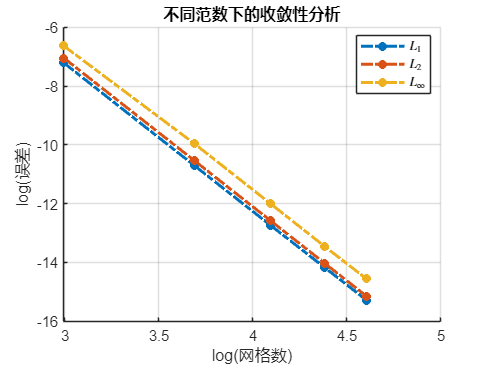


% 绘制误差图
figure('Name', '收敛性分析', 'NumberTitle', 'off');
hold on;
plot(log(mesh_sizes), log(errors_L1), '-.*', 'LineWidth', 2, 'DisplayName', '$L_1$');
plot(log(mesh_sizes), log(errors_L2), '-.*', 'LineWidth', 2, 'DisplayName', '$L_2$');
plot(log(mesh_sizes), log(errors_Linf), '-.*', 'LineWidth', 2, 'DisplayName', '$L_\infty$');
hold off;
xlabel('log(网格数)');
ylabel('log(误差)');
title('不同范数下的收敛性分析');
legend('Interpreter', 'latex', 'Location', 'best');
grid on;